# Nuerieke Lineaire Algebra

## Opgave 1: Gram-Schmidt

clc, clear;

m = 200;
n = 60;
B = randn(m,n);
r = rank(B);
[Q,~] = qr(B);
Q = Q(:,1:r);


D = eye(r,r);

for i=1:r
    D(i,i) = 2^(1-i);
end

V = eye(r,r);

V(1,:) = 1;


A = Q*D*V;


### Maak een figuur. Je ziet dat de fout eerst stijgt en dan afvlakt. Is deze stijging logaritmisch, polynomiaal of exponentieel?

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

y1 = vecnorm(Q1-Q, 2);
y2 = vecnorm(Q2-Q, 2);

### oefening 5

q1_list = zeros(1,n);
q2_list = zeros(1,n);

for i=1:n
    for k=1:i-1
        q1_list(i) = q1_list(i) + 2^(i-1)*2^(k-1)*eps;
    end
    q2_list(i) = 2^(i-1)*eps;
end

### Oefening 8

orth_1 = zeros(1,n);
orth_2 = zeros(1,n);

for i=1:n
  orth_1(i) = norm(eye(i) - Q1(:,1:i)'*Q1(:,1:i));
  orth_2(i) = norm(eye(i) - Q2(:,1:i)'*Q2(:,1:i));
end

figure;
title('Oefening 5', 'FontSize', 30)

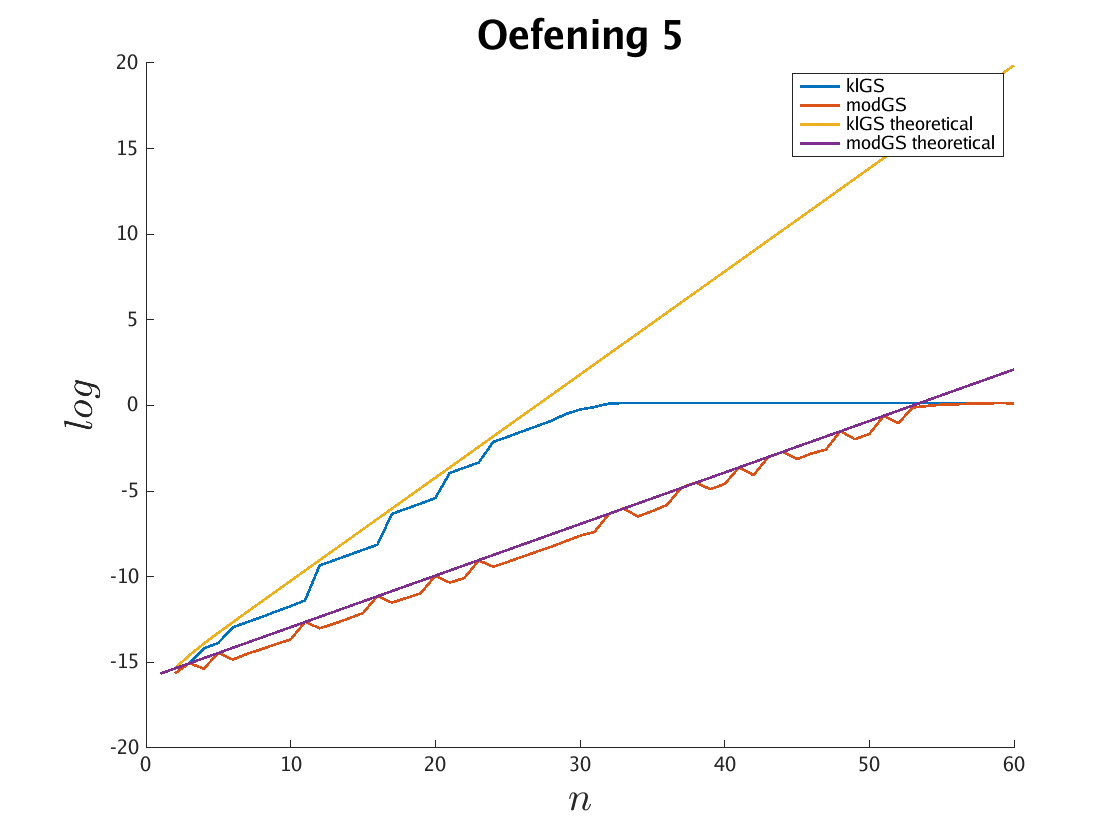

hold on;
plot(log10(y1),'DisplayName','klGS', 'LineWidth', 2);
plot(log10(y2),'DisplayName','modGS', 'LineWidth', 2);
plot(log10(q1_list), 'DisplayName', 'klGS theoretical', 'LineWidth', 2);
plot(log10(q2_list), 'DisplayName', 'modGS theoretical', 'LineWidth', 2);
% plot(log10(orth_1), 'DisplayName', 'klGS I-Q*Q', 'LineWidth', 2);
% plot(log10(orth_2), 'DisplayName', 'modGS I-Q*Q', 'LineWidth', 2);
hold off;
legend('show')
ylabel('$log$','Interpreter','latex', 'FontSize', 30)
xlabel('$n$', 'Interpreter','latex','FontSize', 30)

### Oefening 9

clc, clear;

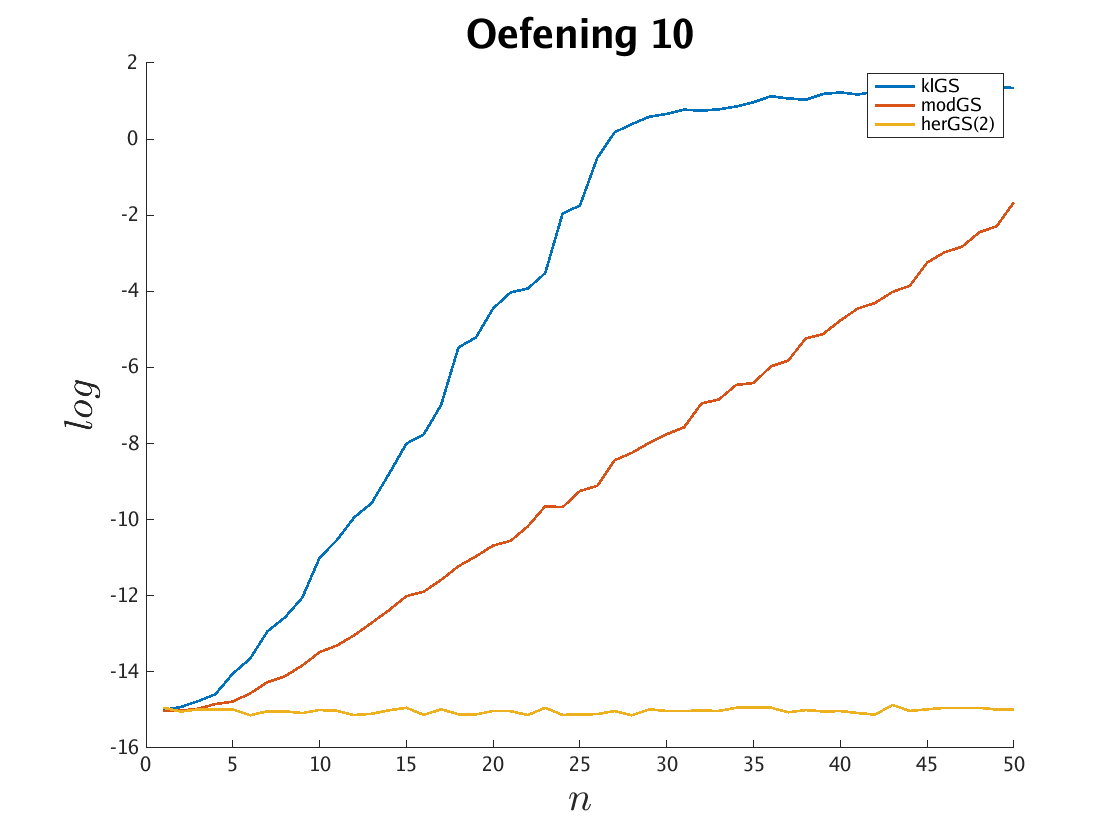

m=200; 
n=50; 
B = randn(m, n);
r = rank(B); 
[Q,~] = qr(B); 
Q_reduced = Q(:,1:r);
V = orth(randn(r));

E1 = zeros(1,r);
E2 = zeros(1,r);
E3 = zeros(1,r);



for k=1:r
    D = diag(2.^linspace(k,0,n)); 
    A = Q_reduced*D*V;
    
    [Q1, R1] = klGS(A);
    [Q2, R2] = modGS(A);
    [Q3, R3] = herGS(A);
    
    e1 = norm(eye(r) - Q1'*Q1);
    e2 = norm(eye(r) - Q2'*Q2);
    e3 = norm(eye(r) - Q3'*Q3);

    E1(k) = e1;
    E2(k) = e2;
    E3(k) = e3;


end

figure;
title("Oefening 10", 'FontSize', 30)
hold on;
plot(log10(E1),'DisplayName','klGS', 'LineWidth', 2);
plot(log10(E2),'DisplayName','modGS', 'LineWidth', 2);
plot(log10(E3),'DisplayName','herGS(2)', 'LineWidth', 2);
hold off;
legend('show')
ylabel('$log$','Interpreter','latex', 'FontSize', 30)
xlabel('$n$', 'Interpreter','latex','FontSize', 30)